# `Εργασία Γενετικών Αλγορίθμων - Άσκηση 4`

## `Θεωρητική ανάλυση προβλήματος`

`Το πρόβλημα χρησιμοποιεί γενετικούς αλγορίθμους για να βρει λύσεις μιας τριτοβάθμιας πολυωνυμικής εξίσωσης. Η εξίσωση είναι η εξής και οι λύσεις της βρίσκονται σε διάστημα [0,2].`

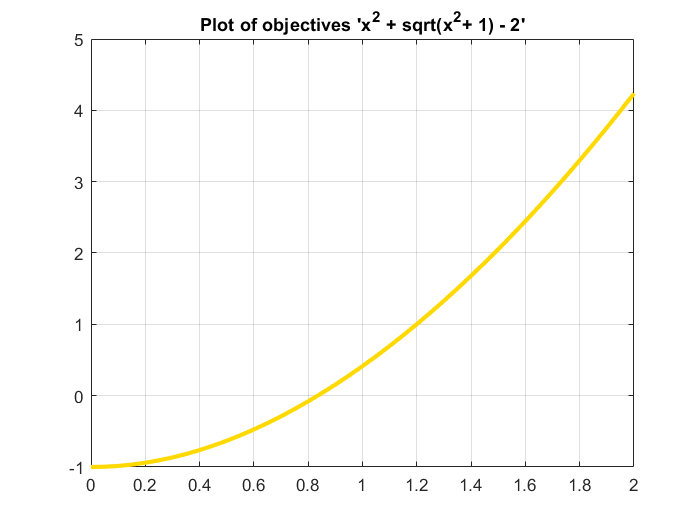

x_t = 0:0.05:2;
func_to_plot = x_t.^(2) + sqrt(x_t.^(2)+ 1) - 2;
plot(x_t, func_to_plot, 'LineWidth', 2.5, 'Color', [1 0.85 0])
title('Plot of objectives ''x^2 + sqrt(x^2+ 1) - 2''');
grid on

`Επειδή επιθυμώ οι λύσεις μου να ανήκουν στο θετικό διάστημα υψώνω στο τετράγωνο την συνάρτηση αλλάζοντας την μορφή της αλλα με ίδιες ρίζες.`

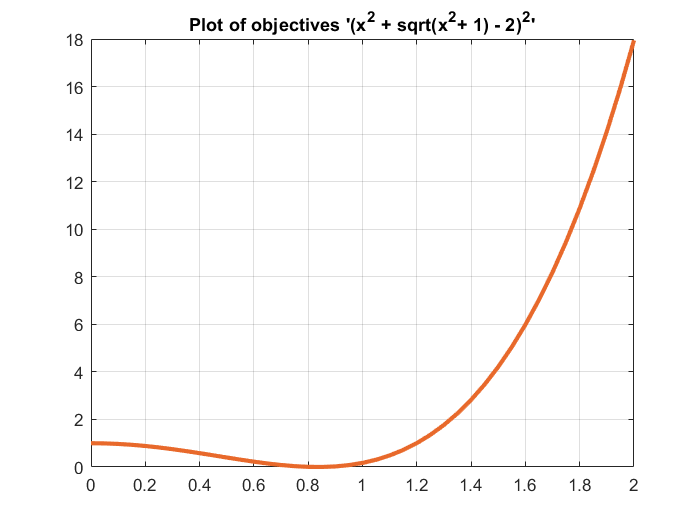

x_t = 0:0.05:2;
func_to_plot = (x_t.^(2) + sqrt(x_t.^(2)+ 1) - 2).^2;
plot(x_t, func_to_plot, 'LineWidth', 2.5, 'Color', [0.9100 0.4100 0.170])
title('Plot of objectives ''(x^2 + sqrt(x^2+ 1) - 2)^2''');
grid on

`Αντίστοιχα δημιουργούμε την παραπάνω συνάρτηση σε νέο αρχείο και θα παρουσιαστεί η διαδικασία με δύο τρόπους. Αρχικά χωρίς την χρήση του "``optimization tool``" μέσω του κώδικα και έπειτα με την χρήση του εργαλείου. Εισάγω την συνάρτηση στον κώδικα μου όπως γράφτηκε παραπάνω αλλά σε αρχείο συνάρτησης. Η συνάρτηση είναι γραμμένη με τρόπο ώστε να βρεθούν λύσεις στα καθορισμένα όρια. Στην συνέχεια θα προβληθούν τα σετ των λύσεων γνωστά ως "Pareto form".`

clc; clear;
disp("This is the function used for Multiobjective Optimization Problem:")

This is the function used for Multiobjective Optimization Problem:


type Equation_fitness.m;


function y = Equation_fitness(x) 
    y = (x.^(2) + sqrt(x.^(2)+ 1) - 2).^2;
end




`Η παραπάνω συνάρτηση έχει μια είσοδο όσες και οι μεταβλητές στο πρόβλημά μας. Η "fitness" συνάρτηση υπολογίζει την τιμή κάθε συνάρτησης, στον προκειμένη μιας, και επιστρέφει ένα διάνυσμα λύσεων, σε αυτή την περίπτωση τρεις λύσεις. Ορίζω τα όρια λύσεων και τον αριθμό λύσεων.`

FitnessFcn = @Equation_fitness; 

nvars = 2;

lb = [0 0]; ub = [2 2];

`Σε αυτό το σημείο γίνεται χρήση του εργαλείου "``gamultiobj``" έναντι του "``optimization tool``". Αποθηκεύονται οι είσοδοι, οι έξοδοι ο λόγος τερματισμού και το αποτέλεσμα κατά σειρά στις παρακάτω μεταβλητές. Συγκεκριμένα στις δύο ρυθμίσεις οπτικοποιώ τα σετ των λύσεων για την μια συνάρτηση που σε κάθε γενιά, στο πρώτο διάγραμμα, και την διαφορετικότητα των λύσεων στο δεύτερο διάγραμμα. Επιπλέον έχουμε ρυθμίσει τα κριτήρια για τον τερματισμό του αλγόριθμου και εμφανίζονται ως πληροφορίες παρακάτω. `

options = optimoptions(@gamultiobj,'PlotFcn',{@gaplotpareto,@gaplotscorediversity,@gaplotrankhist,@gaplotgenealogy});

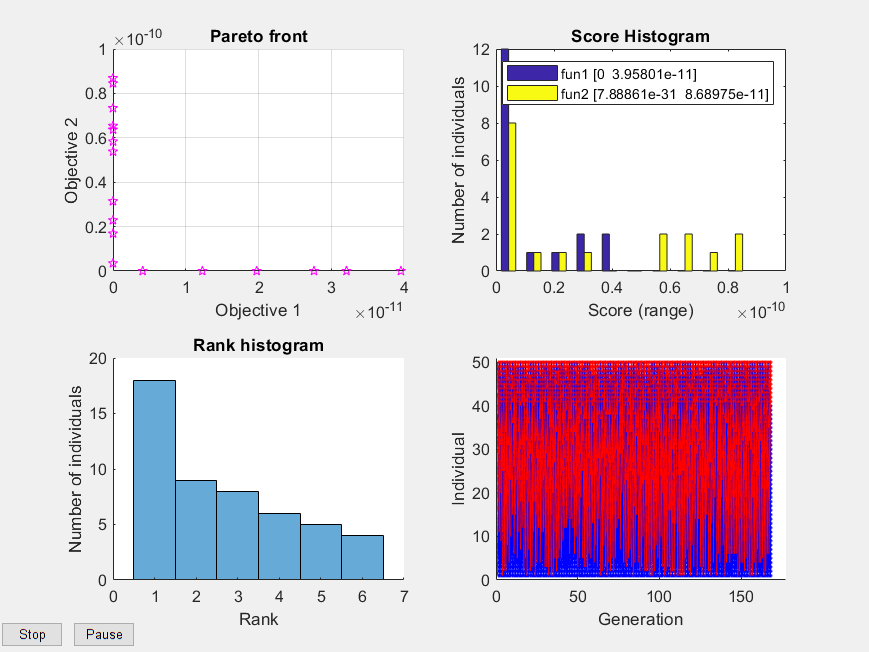

Optimization terminated: average change in the spread of Pareto solutions less than options.FunctionTolerance.


x =     0.8350    0.8350
    0.8350    0.8350
    0.8350    0.8350
    0.8350    0.8350
    0.8350    0.8350
    0.8350    0.8350
    0.8350    0.8350
    0.8350    0.8350
    0.8350    0.8350
    0.8350    0.8350


fval = 	1.0e+-10 *

    0.3958    0.0000
    0.0000    0.7338
    0.0000    0.8453
    0.3958    0.0000
    0.0000    0.5379
    0.0408    0.0000
    0.3209    0.0000
    0.1975    0.0000
    0.1229    0.0000
    0.0000    0.6371


exitflag = 1

output = struct with fields:
        problemtype: 'boundconstraints'
           rngstate: [1×1 struct]
        generations: 169
          funccount: 8450
            message: 'Optimization terminated: average change in the spread of Pareto solutions less than options.FunctionTolerance.'
      maxconstraint: 0
    averagedistance: 6.2042e-12
             spread: 0.2005


population =     0.8350    0.8350
    0.8350    0.8350
    0.8350    0.8350
    0.8350    0.8350
    0.8350    0.8350
    0.8350    0.8350
    0.8350    0.8350
    0.8350    0.8350
    0.8350    0.8350
    0.8350    0.8350


score = 	1.0e+-9 *

    0.0396    0.0000
         0    0.1071
    0.0000    0.0734
    0.0396    0.0000
    0.0396    0.0000
    0.0000    0.0845
         0    0.1071
    0.0396    0.0000
    0.0396    0.0000
    0.0396    0.0000


[x, fval, exitflag, output, population, score] = gamultiobj(FitnessFcn, nvars, [], [], [], [], lb, ub, options)

disp('The number of points on the Pareto front was:' ); size(x,1)

The number of points on the Pareto front was:


ans = 18

`Τώρα αφού διαθέτουμε τον πίνακα λύσεων και αποτελεσμάτων γίνεται η μετατροπή των αριθμών απο δεκαδικών σε δυαδικών. Έχει γραφτεί μια συνάρτηση για αυτόν τον σκοπό ώστε να μετατρέπει και τους δεκαδικούς αριθμούς με υποδιαστολή σε δυαδικούς. Αρχικά επειδή η επιστροφή των δυαδικών λύσεων γίνεται σε μορφή χαρακτήρων, τα μετατρέπω σε strings, και αποθηκεύονται σε πίνακες στην αντίστοιχη μορφή και όχι στην μορφή αριθμών για να μη χαθούν τα υπόλοιπα δυαδικά ψηφία. Δυστυχώς επειδή οι λύσεις είναι κοντά στο μηδεν σε πολυ μεγάλες τάξης ακρίβειας, η δυαδική μετατροπή τους είναι ίδια λόγω των τάξεων κοντά στο μηδέν για αυτο παρατηρούνται ίδια αποτελέσματα στην μετατροπή τους.`

bin_x = string(zeros(size(x,1),size(x,2)));
bin_fval = string(zeros(size(fval,1),size(fval,2)));

for i = 1:size(x,1) 
    bin_x(i,1) = convertCharsToStrings(Dec2Bin(x(i,1)));
    bin_x(i,2) = convertCharsToStrings(Dec2Bin(x(i,2)));
    
    bin_fval(i,1) = convertCharsToStrings(Dec2Bin(fval(i,1)));
    bin_fval(i,2) = convertCharsToStrings(Dec2Bin(fval(i,2)));
end


disp("Binary Values of x's is:"); bin_x

Binary Value of x is:


bin_x = 18×2 string array
    "0.1101010111000010"    "0.1101010111000010"
    "0.1101010111000010"    "0.1101010111000010"
    "0.1101010111000010"    "0.1101010111000010"
    "0.1101010111000010"    "0.1101010111000010"
    "0.1101010111000010"    "0.1101010111000010"
    "0.1101010111000010"    "0.1101010111000010"
    "0.1101010111000010"    "0.1101010111000010"
    "0.1101010111000010"    "0.1101010111000010"
    "0.1101010111000010"    "0.1101010111000010"
    "0.1101010111000010"    "0.1101010111000010"
    "0.1101010111000010"    "0.1101010111000010"
    "0.1101010111000010"    "0.1101010111000010"
    "0.1101010111000010"    "0.1101010111000010"
    "0.1101010111000010"    "0.1101010111000010"
    "0.1101010111000010"    "0.1101010111000010"
    "0.1101010111000010"    "0.1101010111000010"
    "0.1101010111000010"    "0.1101010111000010"
    "0.1101010111000010"    "0.1101010111000010"


disp("Binary Values of fval's is:"); bin_fval

Binary Value of fval is:


bin_fval = 18×2 string array
    "0.0000000000000000"    "0.0000000000000000"
    "0.0000000000000000"    "0.0000000000000000"
    "0.0000000000000000"    "0.0000000000000000"
    "0.0000000000000000"    "0.0000000000000000"
    "0.0000000000000000"    "0.0000000000000000"
    "0.0000000000000000"    "0.0000000000000000"
    "0.0000000000000000"    "0.0000000000000000"
    "0.0000000000000000"    "0.0000000000000000"
    "0.0000000000000000"    "0.0000000000000000"
    "0.0000000000000000"    "0.0000000000000000"
    "0.0000000000000000"    "0.0000000000000000"
    "0.0000000000000000"    "0.0000000000000000"
    "0.0000000000000000"    "0.0000000000000000"
    "0.0000000000000000"    "0.0000000000000000"
    "0.0000000000000000"    "0.0000000000000000"
    "0.0000000000000000"    "0.0000000000000000"
    "0.0000000000000000"    "0.0000000000000000"
    "0.0000000000000000"    "0.0000000000000000"


`Σε αυτό το σημείο γίνεται χρήση του εργαλείου "``optimization tool``" και προβάλλονται τα αποτελέσματα.`

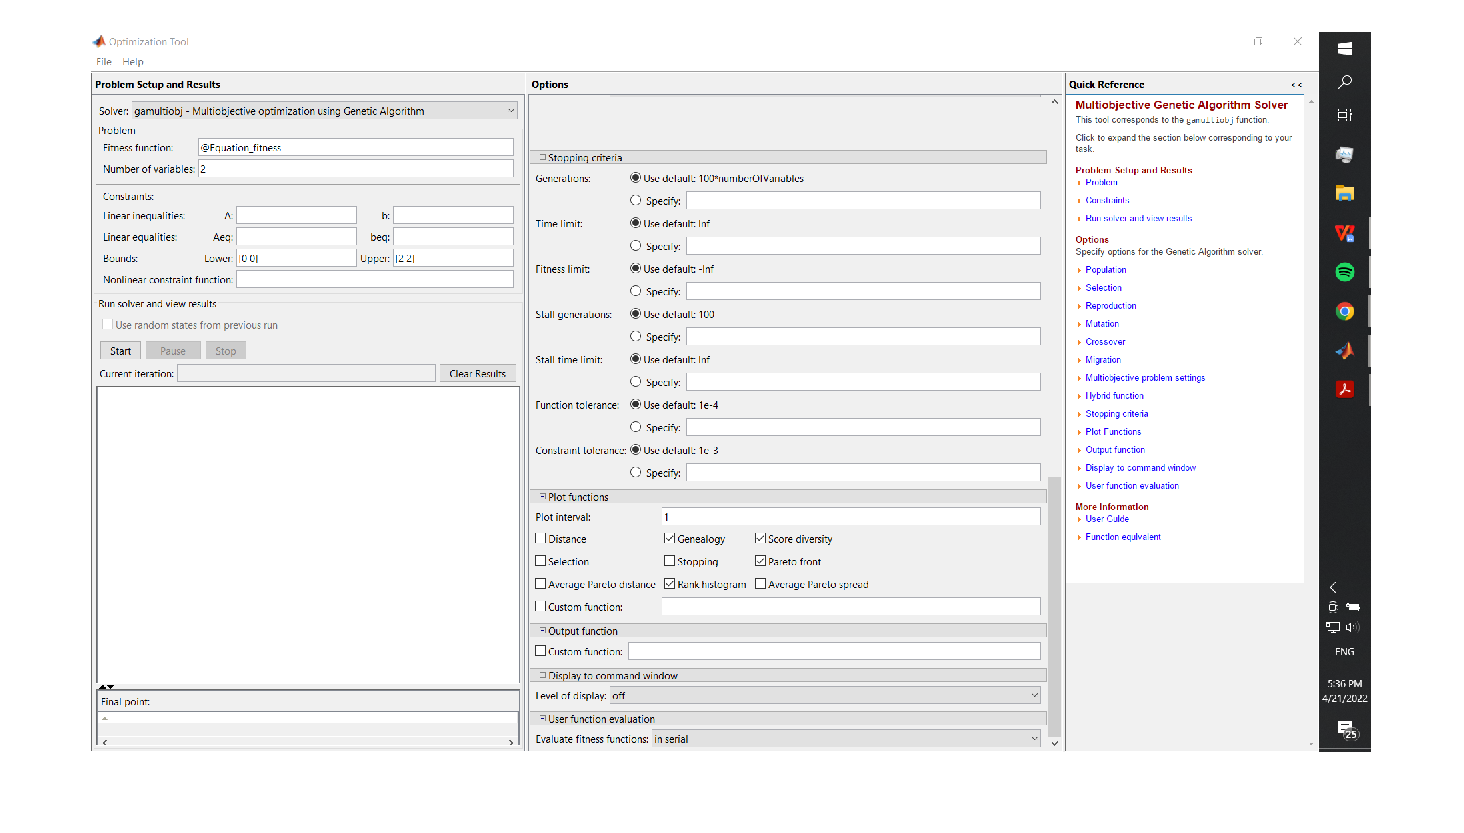

imshow("optimtool_1.PNG")

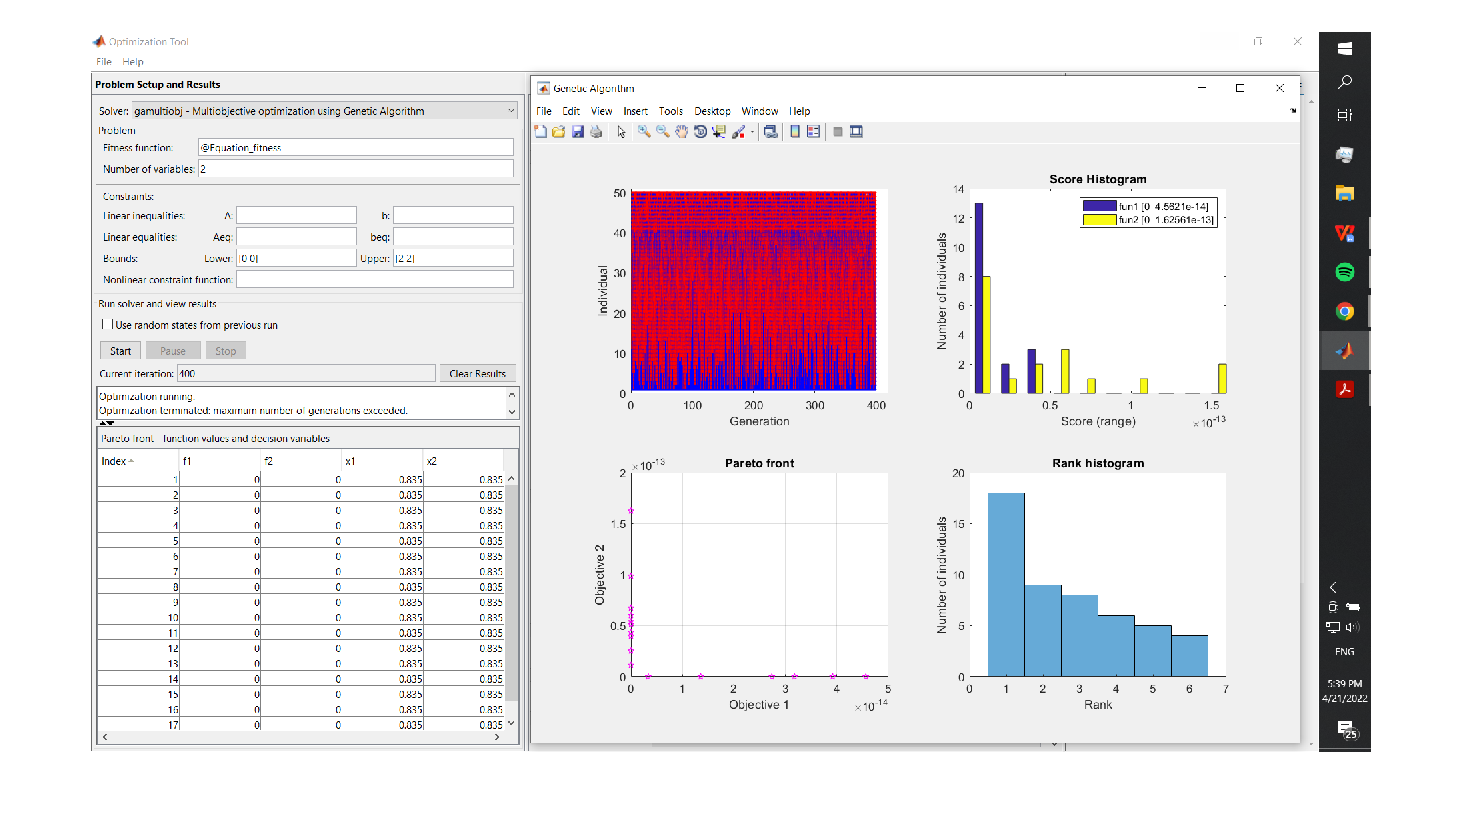

imshow("optimtool_2.PNG")

`Maria Areti Germanou - 57807`